**Diseño de filtros**

En esta parte se desarrollará el diseño de filtros digitales, especialmente el enfoque está en como se puede determinar la frecuencia de corte del filtro.

Inicialmente se cargarán los datos del sensor tanto estático como en movimiento.

S = readmatrix('static.csv');
M = readmatrix('motion.csv');

Para simplificar la explicación se trabajará con 2 de los 6 canales del sensor:

- Acelerómetro en eje Z

- Giróscopo en eje X

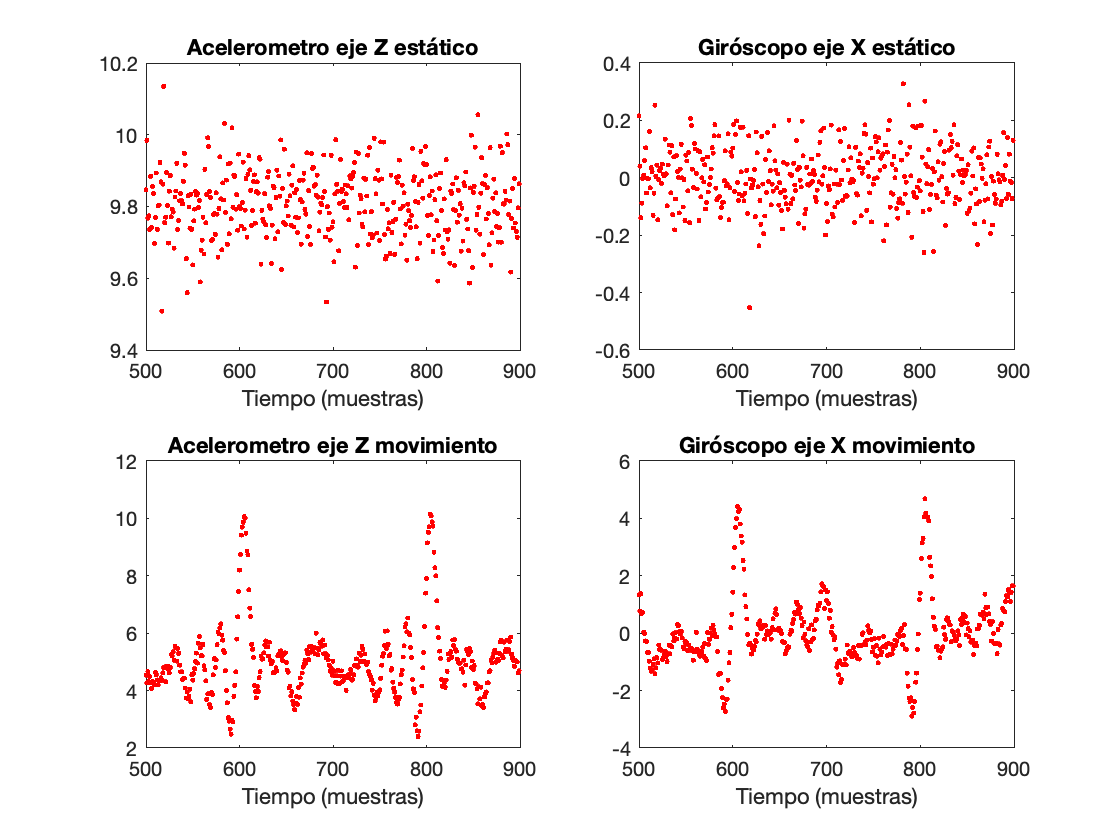

n = 500:899;
figure()
subplot(2,2,1)
plot(n,S(500:899,3),'r.')
title('Acelerometro eje Z estático')
xlabel('Tiempo (muestras)')
subplot(2,2,2)
plot(n,S(500:899,4),'r.')
title('Giróscopo eje X estático')
xlabel('Tiempo (muestras)')
subplot(2,2,3)
plot(n,M(500:899,3),'r.')
title('Acelerometro eje Z movimiento')
xlabel('Tiempo (muestras)')
subplot(2,2,4)
plot(n,M(500:899,4),'r.')
title('Giróscopo eje X movimiento')
xlabel('Tiempo (muestras)')

Los análisis que se realizarán son extrapolables a los otros canales.

Se iniciará por observar los espectros de frecuencia como se hizo en los programas anteriores. Para esta oportunidad se eliminará el componete DC de los espectros para visualizar mejor los posibles armónicos.

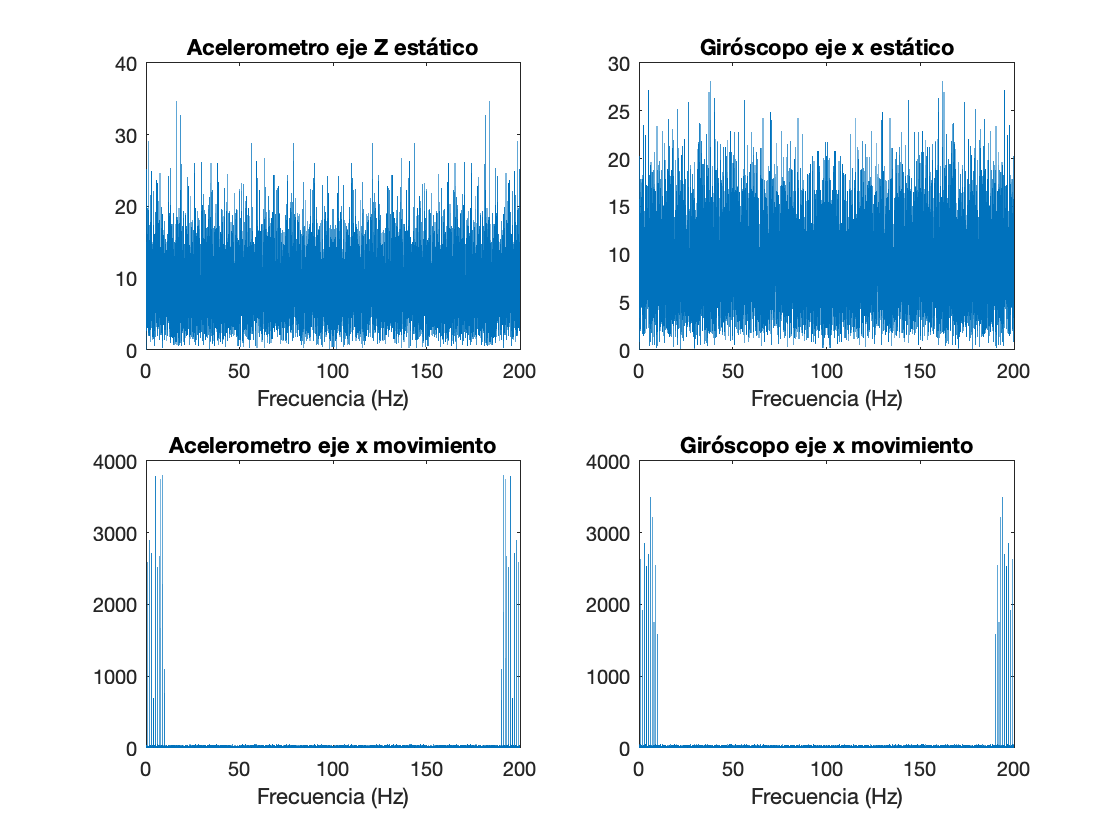

FsAc_z = abs(fft(S(:,3)));
FsAc_z(1) = 0;
FsGy_x = abs(fft(S(:,4)));
FsGy_x(1) = 0;

FmAc_z = abs(fft(M(:,3)));
FmAc_z(1) = 0;
FmGy_x = abs(fft(M(:,4)));
FmGy_x(1) = 0;

fr = [0:9999]*200/length(FsAc_z);
figure()
subplot(2,2,1)
plot(fr,FsAc_z)
title('Acelerometro eje Z estático')
xlabel('Frecuencia (Hz)')
subplot(2,2,2)
plot(fr,FsGy_x)
title('Giróscopo eje x estático')
xlabel('Frecuencia (Hz)')
subplot(2,2,3)
plot(fr,FmAc_z)
title('Acelerometro eje x movimiento')
xlabel('Frecuencia (Hz)')
subplot(2,2,4)
plot(fr,FmGy_x)
title('Giróscopo eje x movimiento')
xlabel('Frecuencia (Hz)')

En esta oportunidad es posible contrastar las diferencias. 

- El orden de magnitud de las amplitudes de los componetes frecuenciales. En las señales estáticas llegan alrededor de 30 o 40. Para las señales con movimiento estas alturas pueden estar cerca de 4000. Esto indica que la señal de interés posee una amplitud mucho mayor que la amplitud del ruido. Esto se conoce como SNR Signal to Noise Ratio.

- Se nota una clara diferencia en el ancho de banda que cubre la señal con movimiento. Se puede ver que va desde cerca de los 0Hz hasta 10 Hz. Mientras que el ruido cubre todo el espectro.

Las condiciones mencionadas conforman un escenario favorable para la aplicación de filtros convencionales (FIR y/o IIR). A continuación se realizará la simulación del la aplicaciónde un filtro IIR.

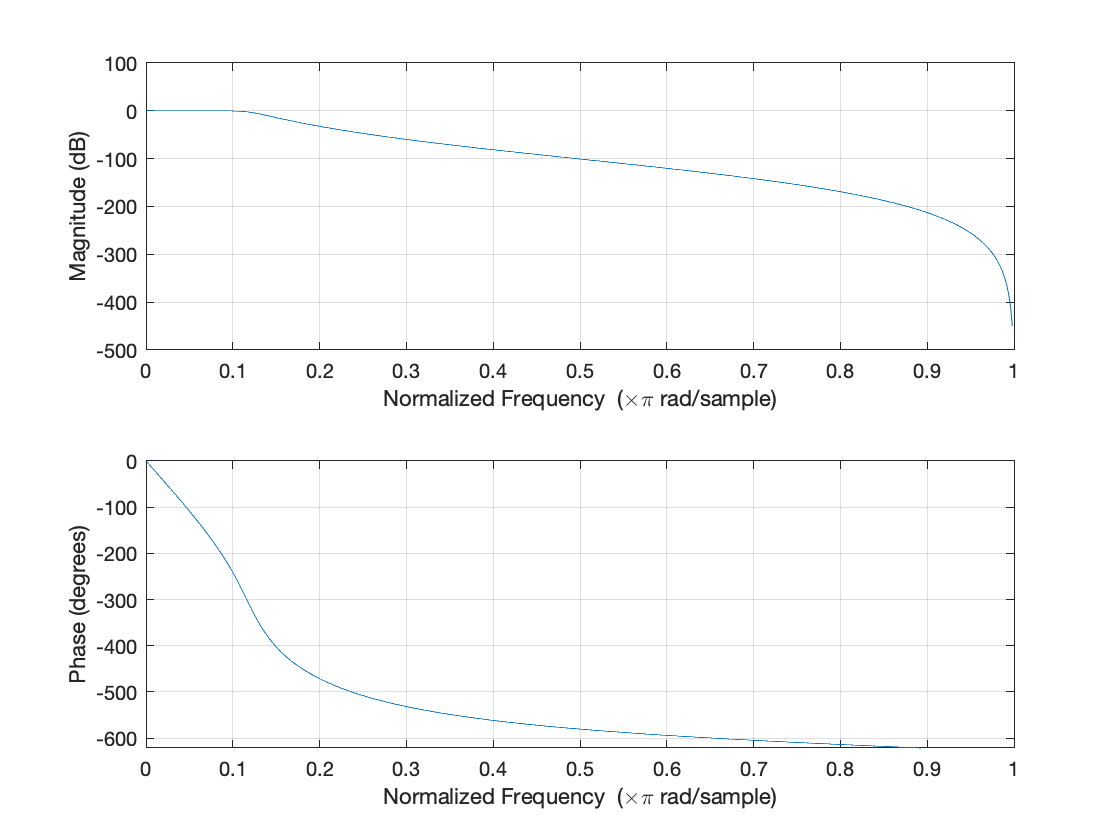

%Filtro IIR metodo de Butterworth
Fs = 200; %muestras/segundo
Fc = 12; %ciclos/segundo
fc = 2*(Fc/Fs); %Pi rad/muestra
[b,a] = butter(7,fc);
figure()
freqz(b,a)

Con la función freqz se pueden observar los gráficos de respeusta en frecuencia del filtro, se interpretan de forma similar a los diagrámas de Bode de los filtros análogos.

En el grafico de magnitud se puede determinar la frecuencia de corte (10 Hz = 0.1 pi*rad/sample) y las bandas de paso y rechazo del filtro.

En el gráfico de fase se puede observar el comportamiento en fase, es decir como se van a ver atrasados los armómicos de la señal, obviamente esto solo es relevante para la bandad de paso.

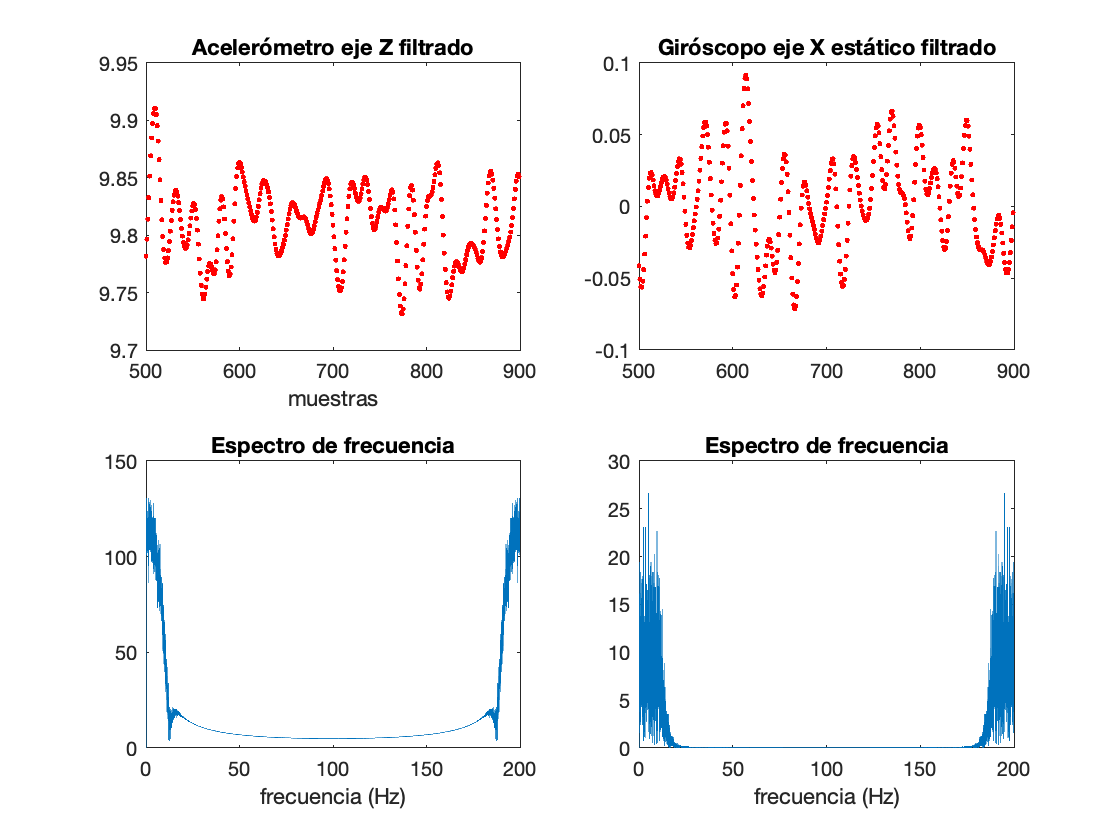


%filtrando señales estáticas
Acf_z = filter(b,a,S(:,3));
Gyf_x = filter(b,a,S(:,4));

Acs_z = abs(fft(Acf_z));
Acs_z(1) = 0;
Gys_x = abs(fft(Gyf_x));
Gys_x(1) = 0;

f = figure();
f.Name = 'Sensor sin movimiento';
subplot(2,2,1)
plot(n,Acf_z(500:899),'r.')
title('Acelerómetro eje Z filtrado')
xlabel('muestras')
subplot(2,2,2)
plot(n,Gyf_x(500:899),'r.')
title('Giróscopo eje X estático filtrado')
subplot(2,2,3)
plot(fr,Acs_z)
title('Espectro de frecuencia')
xlabel('frecuencia (Hz)')
subplot(2,2,4)
plot(fr,Gys_x)
title('Espectro de frecuencia')
xlabel('frecuencia (Hz)')

En los resultados presentados anteriormente se observa como el filtro ha logrado atenuar parte de las bandas correspondientes a las frecuencias superiores a 10 Hz. Dado que el canal Z del acelerómetro tiene un nivel DC importante, la acción del filtro presenta un transitorio que distorsiona la señal de salida, observelo en las gráficas de tiempo y de frecuencia.

El paso siguiente es aplicar el filtro a las señales con movimiento.

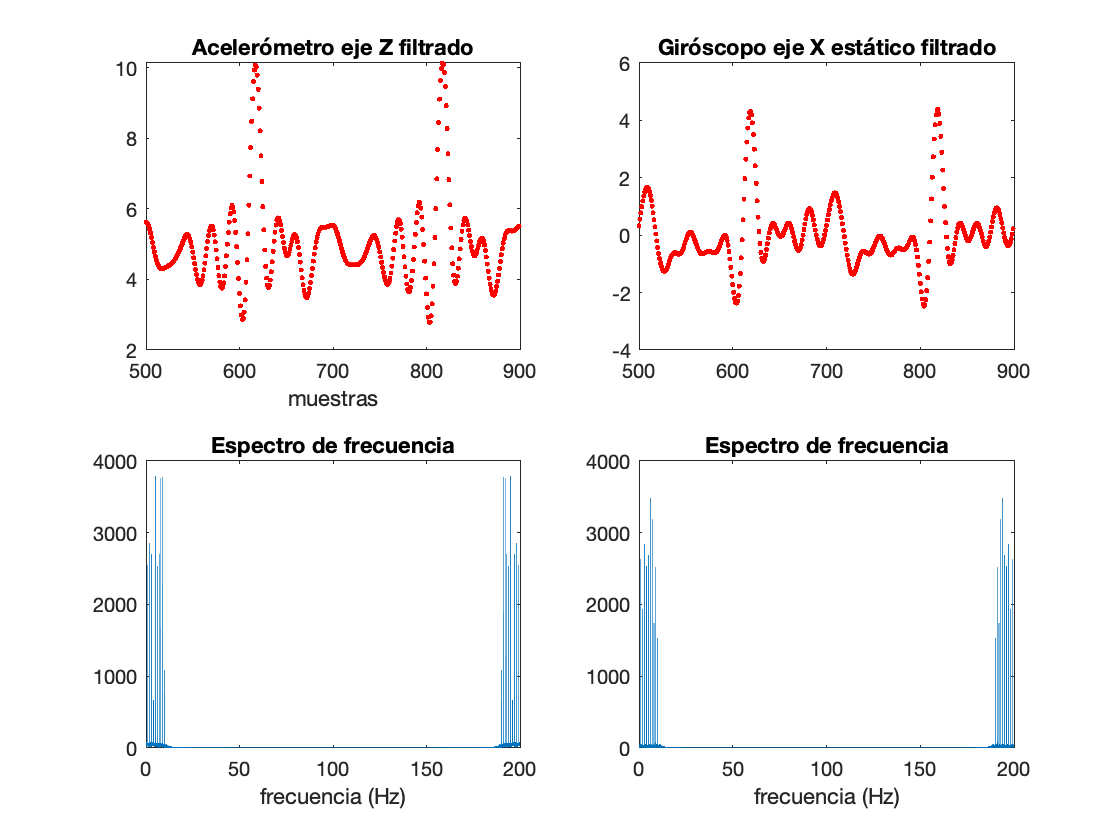

%filtrando señales estáticas
Acf_z = filter(b,a,M(:,3));
Gyf_x = filter(b,a,M(:,4));

Acs_z = abs(fft(Acf_z));
Acs_z(1) = 0;
Gys_x = abs(fft(Gyf_x));
Gys_x(1) = 0;

f = figure();
f.Name = 'Sensor con movimiento';
subplot(2,2,1)
plot(n,Acf_z(500:899),'r.')
title('Acelerómetro eje Z filtrado')
xlabel('muestras')
subplot(2,2,2)
plot(n,Gyf_x(500:899),'r.')
title('Giróscopo eje X estático filtrado')
subplot(2,2,3)
plot(fr,Acs_z)
title('Espectro de frecuencia')
xlabel('frecuencia (Hz)')
subplot(2,2,4)
plot(fr,Gys_x)
title('Espectro de frecuencia')
xlabel('frecuencia (Hz)')